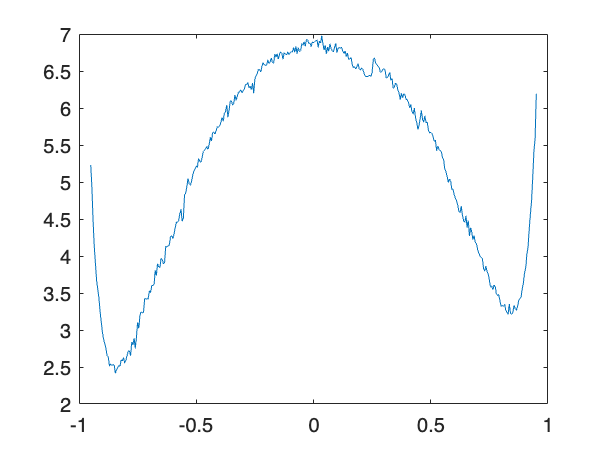

T = 1000000;
m = 20;
n = 20;
N = m * n;
J = 1;
beta = 1/2;
H = 0.0;
mu = 1;
w = 40 * mu;
M_set = -(N*mu-w/2): 2: (N*mu-w/2);
P = zeros(1, length(M_set));
betaA = zeros(1, length(M_set));
A_add = 0;
for i = 1: length(M_set)
    M = M_set(i);
    if mod(i, w/2) == 1
        if i ~= 1
            status = init_status(M1, M2, ...
                mu, m, n);
            [status, pp] = ...
                Ising(status, beta, ...
                J, H, T, M, mu, M1, M2);
            AA = -log(pp);
        end
        M1 = M;
        M2 = M + w;
    end
    status = init_status(M1, M2, mu, m, n);
    [status, P(i)] = ...
        Ising(status, beta, J, H, T, ...
        M, mu, M1, M2);
    betaA(i) = -log(P(i));
    if mod(i, w/2) == 1 && i ~= 1
        A_add = A_add + AA - betaA(i);
    end
    betaA(i) = betaA(i) + A_add;
end
plot(M_set/(N*mu), betaA);